clear variables;
load('usborder.mat','x','y','xx','yy');
rng(3,'twister') % Makes stops in Maine & Florida, and is reproducible
nStops = 200; % You can use any number, but the problem size scales as N^2
stopsLon = zeros(nStops,1); % Allocate x-coordinates of nStops
stopsLat = stopsLon; % Allocate y-coordinates
n = 1;
while (n <= nStops)
    xp = rand*1.5;
    yp = rand;
    if inpolygon(xp,yp,x,y) % tTest if inside the border
        stopsLon(n) = xp;
        stopsLat(n) = yp;
        n = n+1;
    end
end

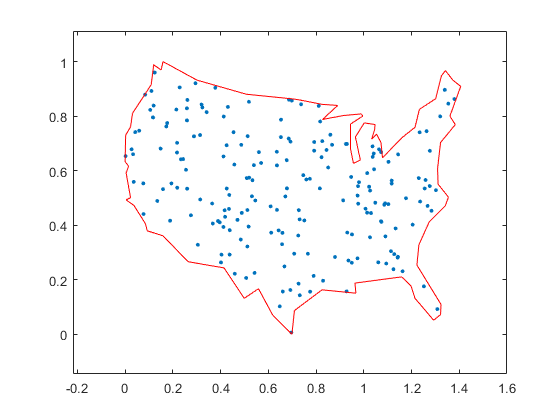

idxs = nchoosek(1:nStops,2);
dist = hypot(stopsLat(idxs(:,1)) - stopsLat(idxs(:,2)), ...
             stopsLon(idxs(:,1)) - stopsLon(idxs(:,2)));
lendist = length(dist);
G = graph(idxs(:,1),idxs(:,2));
figure
hGraph = plot(G,'XData',stopsLon,'YData',stopsLat,'LineStyle','none','NodeLabel',{});
hold on
% Draw the outside border
plot(x,y,'r-')
hold off

tsp = optimproblem;
trips = optimvar('trips',lendist,1,'Type','integer','LowerBound',0,'UpperBound',1);